Beta=59.341;
angle_2 = 0:1:361;
angle_3=zeros(size(angle_2));
angle_4=0:1:360;
angle_5=0:1:360;
angle_6=0:1:360;
angle_7=0:1:360;
omega2=0.52;
omega3=0:1:360;
omega4=0:1:360;
omega6=0:1:360;
omega7=0:1:360;
alpha2=0;
alpha3=0:1:360;
alpha4=0:1:360;
alpha6=0:1:360;
alpha7=0:1:360;
x0=[0,0];
x=zeros(2,361);
y=zeros(2,361);
options = optimset('display', 'off');
for i=1 :length(angle_2)
 x(:,i)=fsolve(@position1,[0.6 1],options,angle_2(i))*180/pi;
 angle_3(i)=x(1,i);
 angle_4(i)=x(2,i);
 angle_5(i)=(-180-Beta)+angle_3(i);
end
for i=1 :length(angle_2)
y(:,i)=fsolve(@Omega1,[0 0],options,[omega2,angle_2(i),angle_3(i),angle_4(i)]);
 omega3(i)=y(1,i);
 omega4(i)=y(2,i);
end
for i=1 :length(angle_2)
z(:,i)=fsolve(@Alpha1,[0 0],options,[alpha2,angle_2(i),angle_3(i),angle_4(i),omega2,omega3(i),omega4(i)]);
 alpha3(i)=z(1,i);
 alpha4(i)=z(2,i);
end
for i=1 :length(angle_2)
 x(:,i)=fsolve(@position2,[6 2.094],options,[angle_4(i),angle_5(i)])*180/pi;
 angle_6(i)=x(1,i);
 angle_7(i)=x(2,i);
end
for i=1 :length(angle_2)
 x(:,i)=fsolve(@Omega2,[0,0],options,[omega4(i),omega3(i),angle_4(i),angle_5(i),angle_6(i),angle_7(i)]);
 omega6(i)=x(1,i);
 omega7(i)=x(2,i);
end
for i=1 :length(angle_2)
 x(:,i)=fsolve(@Alpha2,[0,0],options,[alpha4(i),alpha3(i),angle_4(i),angle_5(i),angle_6(i),angle_7(i),omega4(i),omega3(i),omega6(i),omega7(i)]);
 alpha6(i)=x(1,i);
 alpha7(i)=x(2,i);
end
nexttile;
plot(angle_2,angle_3)
xlabel('Theta2');
ylabel('Theta3');
grid;
hold;

Current plot held


nexttile;
plot(angle_2,angle_4)
xlabel('Theta2');
ylabel('Theta4');
grid;
hold;

Current plot held




nexttile;
plot(angle_2,omega3)
xlabel('Theta2');
ylabel('Omega3');
grid;
hold;

Current plot held


nexttile;
plot(angle_2,omega4)
xlabel('Theta2');
ylabel('Omega4');
grid;
hold;

Current plot held



nexttile;
plot(angle_2,alpha3)
xlabel('Theta2');
ylabel('Alpha3');
grid;
hold;

Current plot held


nexttile;
plot(angle_2,alpha4)
xlabel('Theta2');
ylabel('Alpha4');
grid;
hold;

Current plot held



nexttile;
plot(angle_2,angle_6)
xlabel('Theta2');
ylabel('Theta6');
grid;
hold;

Current plot held


nexttile;
plot(angle_2,angle_7)
xlabel('Theta2');
ylabel('Theta7');
grid;
hold;

Current plot held



nexttile;
plot(angle_2,omega6)
xlabel('Theta2');
ylabel('Omega6');
grid;
hold;

Current plot held


nexttile;
plot(angle_2,omega7)
xlabel('Theta2');
ylabel('Omega7');
grid;
hold;

Current plot held



nexttile;
plot(angle_2,alpha6)
xlabel('Theta2');
ylabel('Alpha6');
grid;
hold;

Current plot held


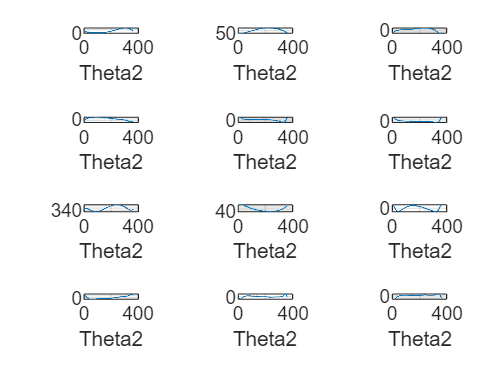

Current plot held


nexttile;
plot(angle_2,alpha7)
xlabel('Theta2');
ylabel('Alpha7');
grid;
hold;